#### **Fig 3B**

*Author: Yi-Shiou Duh (allenduh@stanford.edu)*

*Date: 3/18/2024*

*FDTD scripts*

    *plane_wave_small_box_setup.lsf  -- Setup FDTD environment*

    *plane_wave_small_box_run.lsf -- Run FDTD*

*This script*

- *Plot field distribution*

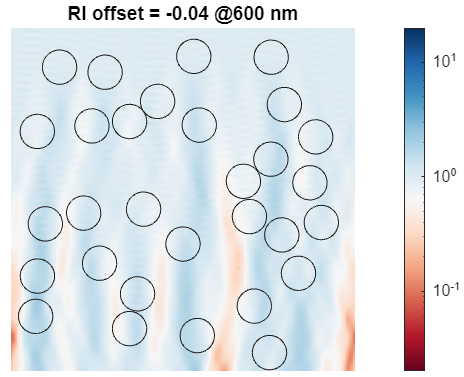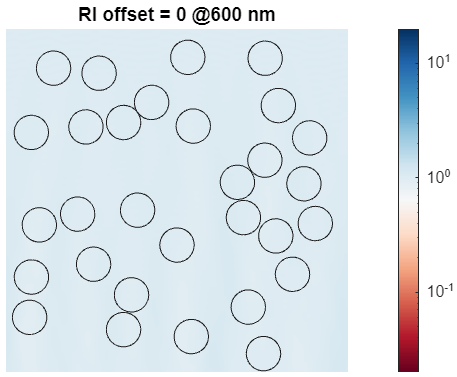

idx = 18; % Read the FDTD file 3 - 1.33 ; 8 - 1.38; 13 - 1.43; 18 - 1.48

background_index = 1.31 : 0.01: 1.5;

RI_offset = background_index(idx) - 1.43;

load(['plane_wave_smallbox_03212024_index_'  num2str(idx)])

mmUnit = 10 ^ -3;
nmUnit = 10 ^ -9; 
umUnit = 10 ^ -6; 
c0 = 299792458;

**Select wavelength of interest**

% Wavelength to plot
wavelengthIndex = 1;   % 1: 600nm, 2: 640nm, 3: 680nm
lambda = fullField_lambda(wavelengthIndex); 
wavelength = lambda / nmUnit;

**Select field distribution range**

% X, Y coordinates
xCoordinate = fullField_xCoordinate;
yCoordinate = fullField_yCoordinate;  
ymin = yCoordinate(1);
ymax = yCoordinate (end);

Ex_scatter = fullField_Ex(:, :, 1, wavelengthIndex); % (:, :, indexof z = 1, wavelengthIndex from 1 to 3)
Ey_scatter = fullField_Ey(:, :, 1, wavelengthIndex);
E_square =  abs(Ex_scatter' .^ 2) + abs(Ey_scatter' .^ 2); 

**Plot field distribution **

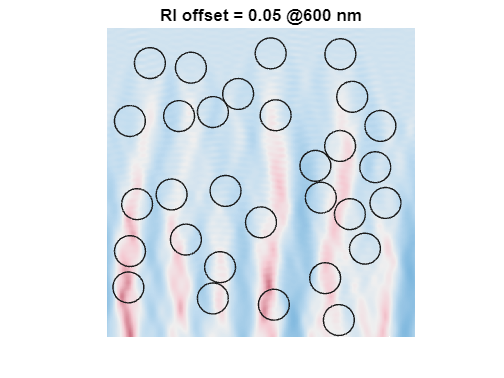

% Plot field distribution
close(figure(14)); figure(14)
imagesc(xCoordinate / umUnit, yCoordinate / umUnit, E_square); hold on

% Draw Scatter circles
numOfParticle = size(xLocList, 1);
for p = 1 : numOfParticle
    circle(xLocList(p) / umUnit, yLocList(p) / umUnit, 0.5);
end
mycmap = importdata('colormap_2023-02-21_blue-red_v4.mat');
ax = gca; colormap(ax,mycmap); 
clim([0.2*10^-1 20]) % unify the color bar range
set(gca,'ColorScale','log');
title(['RI offset = ' num2str(RI_offset)  ' @' num2str(wavelength) ' nm'])
ax = gca; ax.FontSize = 13; shading flat;  ax.YDir= 'normal'; axis image; view(2);    
axis([-5 5 1 11]); axis off;
camroll(180)

function circle(x, y, r)
    %x and y are the coordinates of the center of the circle
    %r is the radius of the circle
    %0.01 is the angle step, bigger values will draw the circle faster but
    %you might notice imperfections (not very smooth)

    ang = 0 : 0.01 : 2 * pi; 
    xp = r * cos(ang);
    yp = r * sin(ang);
    plot(x + xp, y + yp, 'Linewidth', 0.2, 'color', [0.1,0.1,0.1]); hold on
end